addpath('./datos')
addpath('./funciones')

**Tarea 5a: **Utilizando como datos la matriz training

load('Tarea4.mat')

umbral = 0.01;
display=0; %no sacar grafica

VQini= [];

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

Starting parallel pool (parpool) using the 'local' profile ...



Obtén con Kmeans cuantificadores vectoriales de 1 a 16 bits (umbral = 0,01).

for nbits = 1 : 16
    horaInicial = clock;
    [VQ, vDist no_asig] = Kmeans (training, nbits, VQini, umbral, display);
    horaFinal=clock;
    vectorHorasEstimacion(nbits,:) = etime(horaFinal, horaInicial);

Almacena los 16 VQs en una única matriz VQt de forma que las dos primeras filas se correspondan con los centroides del VQ de 1 bit, las cuatro siguientes con los centroides del VQ de 2 bits, etc.

    if nbits == 1
        VQt = VQ;
    else 
        VQt = vertcat(VQt, VQ);
    end
end

Registra el tiempo que tarda en estimarse cada uno de los 16 VQs y represéntalo en función del número de bits.

horasEstimacion = sum(vectorHorasEstimacion)

n=1:1:16;
figure
plot(n,vectorHorasEstimacion); 
grid
xlabel('n(bits)')
ylabel('segundos estimación)')
title("Tiempo que tarda en estimarse los VQs")
grid

Guarda la matriz VQt y los tiempos registrados en el fichero VQt.mat.

save ('VQt.mat', 'VQt', 'vectorHorasEstimacion');

save 5a.mat

**Tarea 5b:**

load ('VQt.mat', 'VQt', 'vectorHorasEstimacion');

[valores_training_5s, fs_training_5s] = audioread('tvg_training_5s.wav');

data_5s=reshape(valores_training_5s',2,length(valores_training_5s)/2)';

SNRq=[];

for nbits = 1:1:16
    
    % Extraigo de la matriz VQt las filas correspondientes al VQ de nbits
    % de la iteración correspondiente
    if nbits == 1
        filainicial = 1;
        filafinal = 2;
    else 
        filainicial = filainicial + 2^(nbits-1);
        filafinal = filainicial + 2^nbits - 1;      
    end
    
    VQi = VQt (filainicial:filafinal, :);
     
    dataq_5s = VQuantize (data_5s, VQi);
   
    % Pares de muestras a vector adecuadamente ordenado

    temp=dataq_5s';
    
    y_5s=temp(:);

    % Tenéis un traspuesto en vuestra SNR por lo que tengo que añadir:

    y_5s=y_5s';

    SNRq=[SNRq, SNR(valores_training_5s, y_5s)];
   
end

xsc=1;
for n=1:1:8
    [training_5s_QMR_nb, e_training_5s_QMR_nb] = qmidriser(valores_training_5s, xsc, n);
    SNRq_QMR(n) = SNR(valores_training_5s, training_5s_QMR_nb);
end

fs=8*10^3;
    
nb=1:1:16;
n=1:1:8;
Rb_1a16 = fs*(nb/2);      % Rb entre [4 kB - 64 kB]
Rb_1a8 = fs*n;

Rb_1a8 =         8000       16000       24000       32000       40000       48000       56000       64000


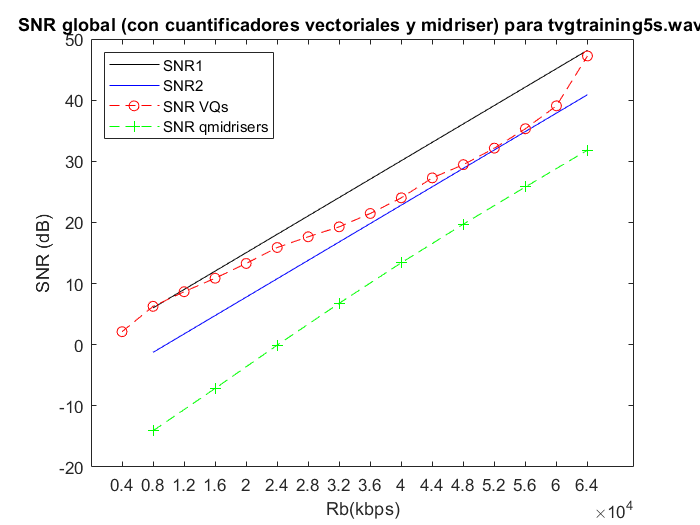

figure
plot(Rb_1a8,6.02*n,'k')
hold on;
plot(Rb_1a8,6.02*n-7.27,'b')
hold on;
%plot(Rb,SNRq(1:length(Rb)),'r--o');
plot(Rb_1a16,SNRq,'r--o');
ax = gca; 
ax.XTick = Rb_1a16; 
grid
hold on;plot(Rb_1a8,SNRq_QMR,'g--+');
ax = gca; 
ax.XTick = Rb_1a16; 
xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend({'SNR1','SNR2', 'SNR VQs','SNR qmidrisers'}, 'Location', 'northwest')
title("SNR global (con cuantificadores vectoriales y midriser) para tvgtraining5s.wav ")
grid

**Tarea 5c:**

load ('VQt.mat', 'VQt', 'vectorHorasEstimacion');

[valores_test_5s, fs_test_5s] = audioread('tvg_test_5s.wav');

data_5s=reshape(valores_test_5s',2,length(valores_test_5s)/2)';

SNRq=[];

for nbits = 1:1:16
    
    % Extraigo de la matriz VQt las filas correspondientes al VQ de nbits
    % de la iteración correspondiente
    if nbits == 1
        filainicial = 1;
        filafinal = 2;
    else 
        filainicial = filainicial + 2^(nbits-1);
        filafinal = filainicial + 2^nbits - 1;      
    end
    
    VQi = VQt (filainicial:filafinal, :);
     
    dataq_5s = VQuantize (data_5s, VQi);
   
    % Pares de muestras a vector adecuadamente ordenado

    temp=dataq_5s';
    
    y_5s=temp(:);

    % Tenéis un traspuesto en vuestra SNR por lo que tengo que añadir:

    y_5s=y_5s';

    SNRq=[SNRq, SNR(valores_test_5s, y_5s)];
   
end

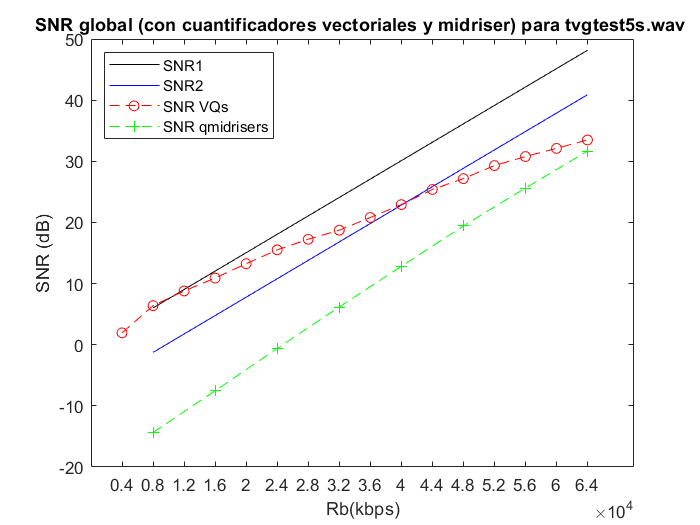

xsc=1;
for n=1:1:8
    [test_5s_QMR_nb, e_test_5s_QMR_nb] = qmidriser(valores_test_5s, xsc, n);
    SNRq_QMR(n) = SNR(valores_test_5s, test_5s_QMR_nb);
end

fs=8*10^3;

nb=1:1:16;
n=1:1:8;
Rb_1a16 = fs*(nb/2);      % Rb entre [4 kB - 64 kB]
Rb_1a8 = fs*n;
figure
plot(Rb_1a8,6.02*n,'k')
hold on;
plot(Rb_1a8,6.02*n-7.27,'b')
hold on;
%plot(Rb,SNRq(1:length(Rb)),'r--o');
plot(Rb_1a16,SNRq,'r--o');
ax = gca; 
ax.XTick = Rb_1a16; 
grid
hold on;plot(Rb_1a8,SNRq_QMR,'g--+');
ax = gca; 
ax.XTick = Rb_1a16; 
xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend({'SNR1','SNR2', 'SNR VQs','SNR qmidrisers'}, 'Location', 'northwest')
title("SNR global (con cuantificadores vectoriales y midriser) para tvgtest5s.wav ")
grid